Matlab code for the Course: **Modelling and Simulation Mechatronics System**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

### Initialize by cleaning memory and widows

clear all;
close all;

### **Load the Pendulum model ODE**

% load the Pendulum model in the variable ode
mass    = 1;
gravity = 9.81;
ode     = ParabolicPendulum4EQ( mass, gravity );

### Initialize 3 solver for comparison

solver_1 = Collatz();
solver_2 = RK4();
solver_3 = GaussLegendre4();

LEGEND = {'Collatz', 'RK4','GaussLegendre4'};

solver_1.setODE(ode);
solver_2.setODE(ode);
solver_3.setODE(ode);

### Set time step and inital conditions for solvers

Tmax = 4;
h    = 0.01;
tt   = 0:h:Tmax;
% setup initial condition
%x0      = 1;
%y0      = 1;
%u0      = 0;
%v0      = 0;
x0      = 0;
y0      = 1;
u0      = -2;
v0      = 0;
ini     = [x0;y0;u0;v0]

ini =      0
     1
    -2
     0


### Compute solutions

sol_1 = solver_1.advance( tt, ini, false, true, 100 );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_2 = solver_2.advance( tt, ini, false, true, 100 );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
At t(325)=3.24 ||x||_inf = 1655.43, computation interrupted


sol_3  = solver_3.advance( tt, ini, false, true, 100 );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


### Extract computed solution

x_1 = sol_1(1,:);
y_1 = sol_1(2,:);

x_2 = sol_2(1,:);
y_2 = sol_2(2,:);

x_3 = sol_3(1,:);
y_3 = sol_3(2,:);

### Plot computed solution

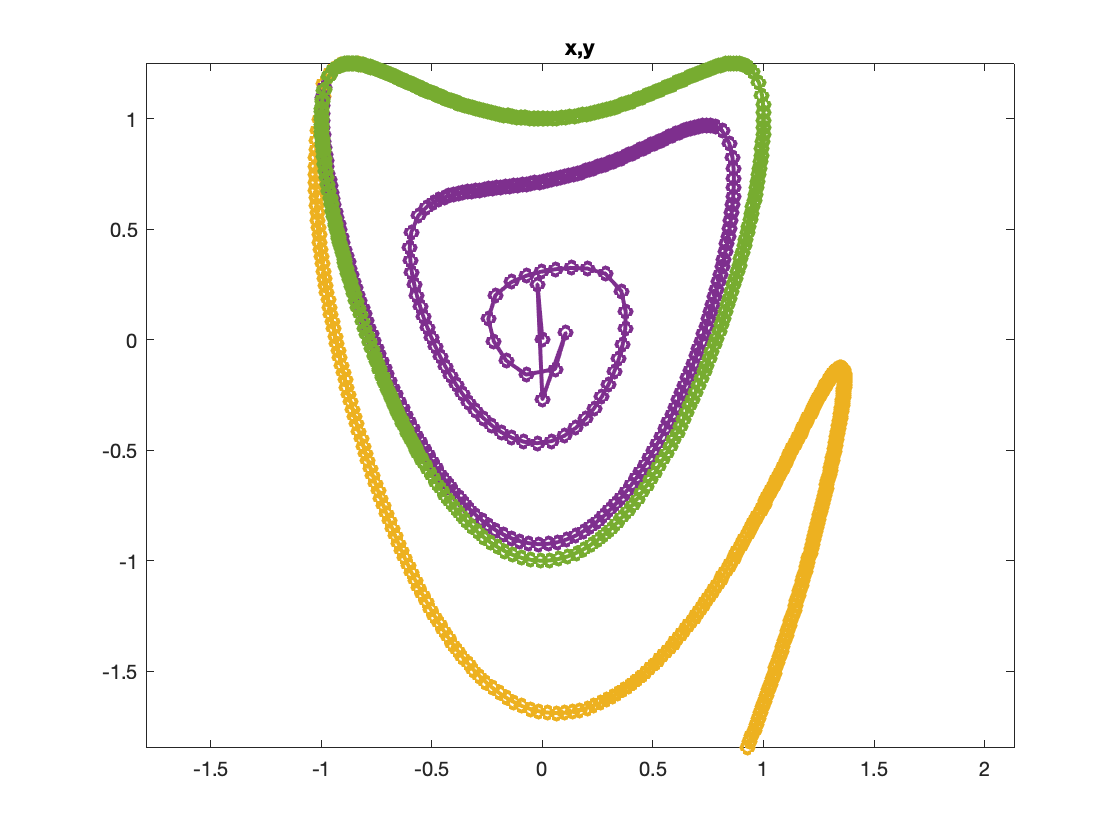

h = figure();
xx = -1:0.01:1;
plot( xx, xx.^2+sqrt(1-xx.^2), '-', 'Linewidth', 1, 'Color','green' );
hold on;
plot( xx, xx.^2-sqrt(1-xx.^2), '-', 'Linewidth', 1, 'Color','cyan' );      % get mass position

axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_3, y_3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

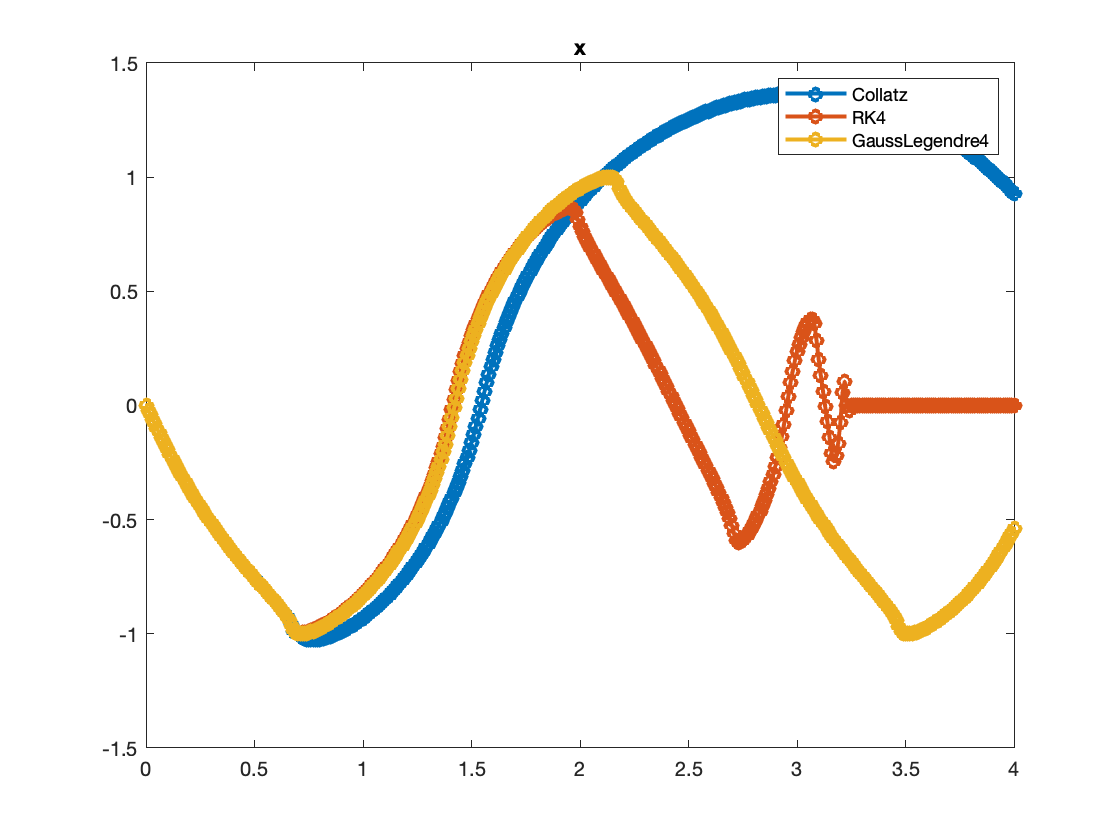

h = figure();
plot( tt, x_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

### Make animation of the solution

if false
  figure('Position', [1 1 1200 400]);
  for k=1:10:length(tt)
    subplot(1,3,1);
    ode.plot( tt(k), sol_1(:,k));
    title(LEGEND{1});
    subplot(1,3,2);
    ode.plot( tt(k), sol_2(:,k));
    title(LEGEND{2});
    subplot(1,3,3);
    ode.plot( tt(k), sol_3(:,k));
    title(LEGEND{3});
    drawnow limitrate;
    pause(0.01);
  end
end

### Compute solutions activating projection

sol_1 = solver_1.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
At t(297)=2.96 ||x||_inf = 5497.76, computation interrupted


sol_2 = solver_2.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_3 = solver_3.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


### Extract computed solution

x_1 = sol_1(1,:);
y_1 = sol_1(2,:);

x_2 = sol_2(1,:);
y_2 = sol_2(2,:);

x_3 = sol_3(1,:);
y_3 = sol_3(2,:);

### Plot computed solution

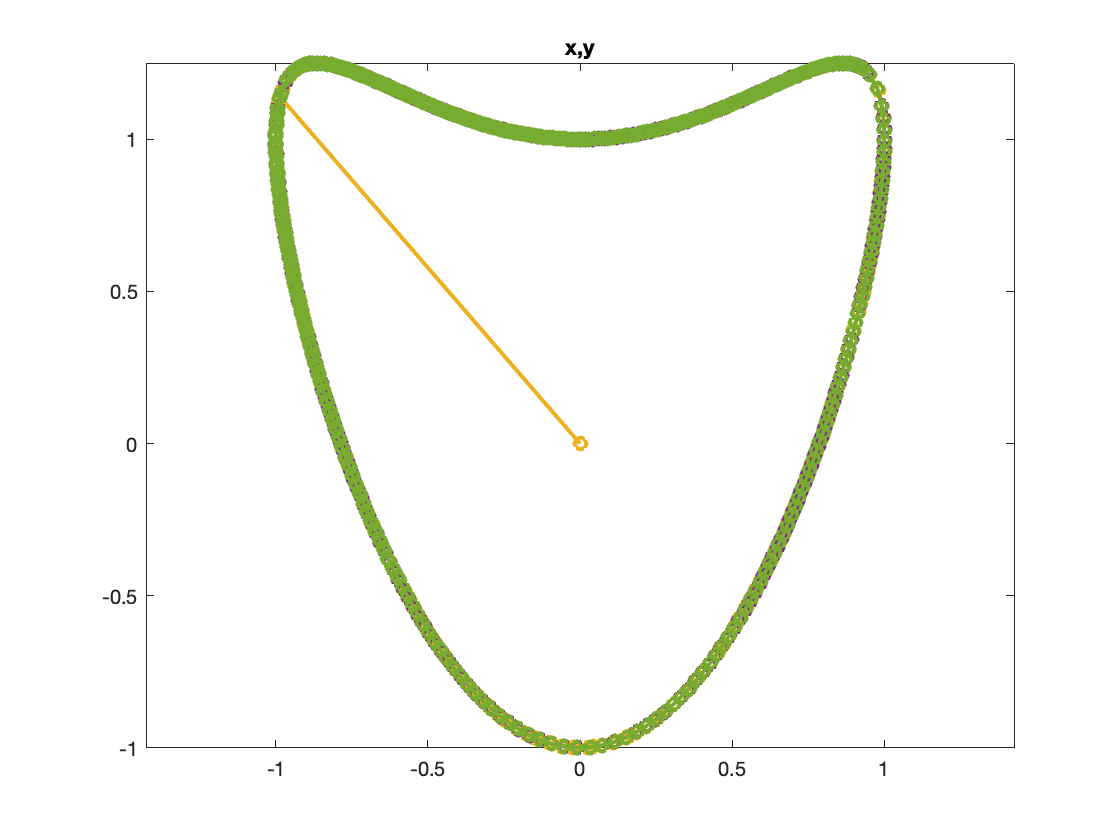

h = figure();
xx = -1:0.01:1;
plot( xx, xx.^2+sqrt(1-xx.^2), '-', 'Linewidth', 1, 'Color','green' );
hold on;
plot( xx, xx.^2-sqrt(1-xx.^2), '-', 'Linewidth', 1, 'Color','cyan' );      % get mass position

axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_3, y_3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

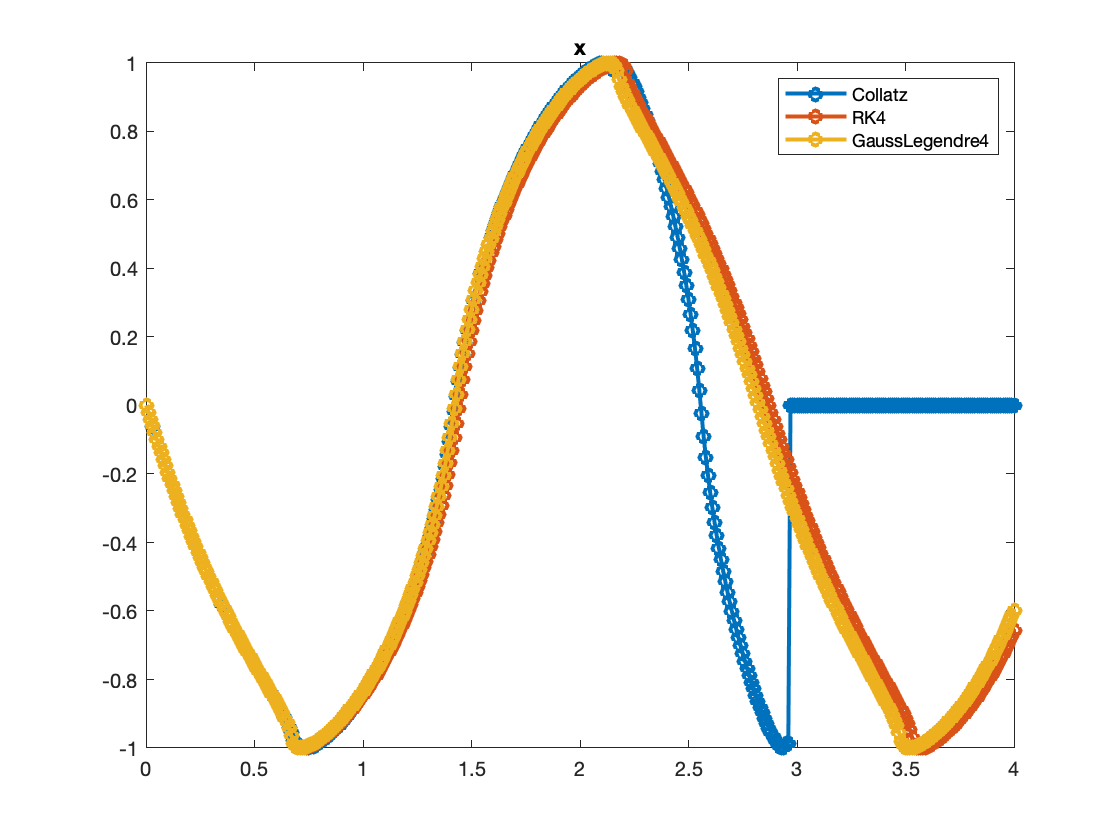

h = figure();
plot( tt, x_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_3,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

### Make animation of the solution

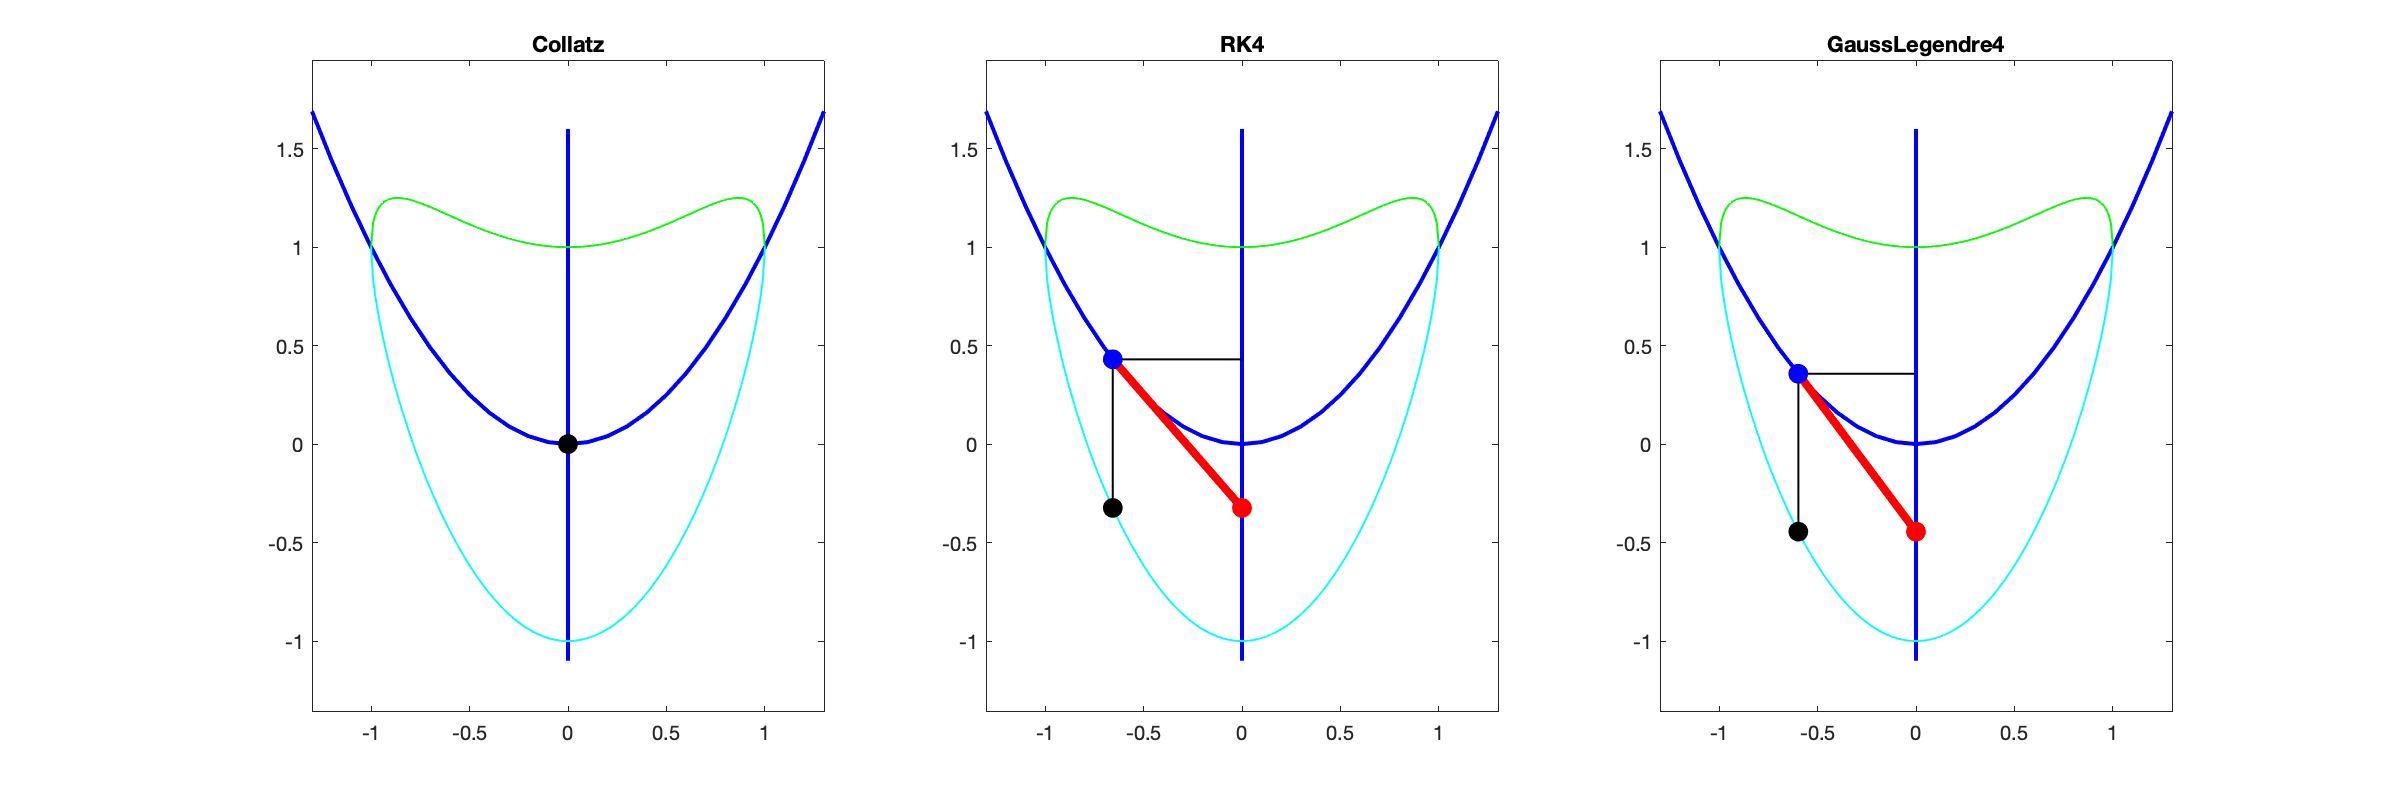

h = figure('Position',[0 0 1200 400]);
for k=1:10:length(tt)
  subplot(1,3,1);
  ode.plot( tt(k), sol_1(:,k));
  title(LEGEND{1});
  subplot(1,3,2);
  ode.plot( tt(k), sol_2(:,k));
  title(LEGEND{2});
  subplot(1,3,3);
  ode.plot( tt(k), sol_3(:,k));
  title(LEGEND{3});
  drawnow limitrate;
  pause(0.01);
end